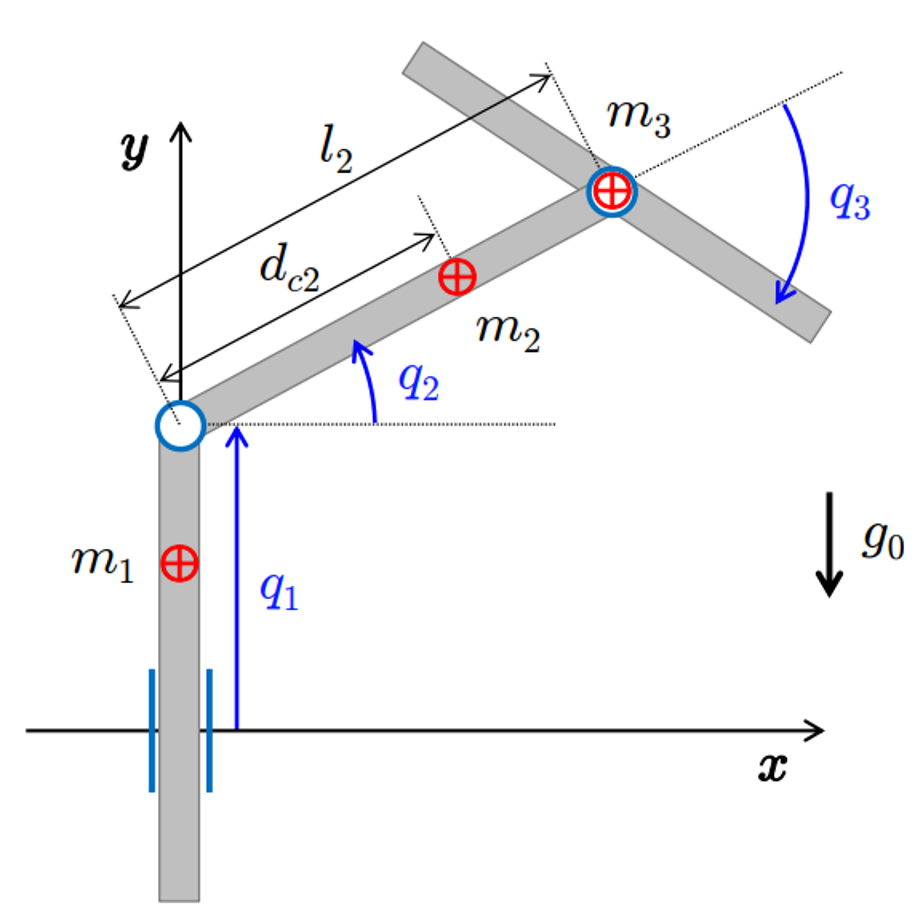

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms m1 m2 m3 d1 d2 d3 l2 I2 I3 g0 positive

% Joint 1
T1 = 0.5*m1*q_dot_1^2

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


% Joint 2
x2 = d2*cos(q2);
y2 = q1+d2*sin(q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + + diff(x2,q3)*q_dot_3

$$vx2 = -d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)$$

vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3

$$vy2 = {\dot{q}}_{1}+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)$$


T2_tr = 0.5*m2*[vx2 vy2 0]*[vx2; vy2; 0;];
T2_rot = 0.5*I2*[0 0 q_dot_2]*[0; 0; q_dot_2;];
T2 = T2_rot+T2_tr

$$T2 = \frac{m_{2}\,{\left({\dot{q}}_{1}+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Joint 3
x3 = l2*cos(q2);
y3 = q1+l2*sin(q2);

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3

$$vx3 = -l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)$$

vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3

$$vy3 = {\dot{q}}_{1}+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)$$


T3_tr = 0.5*m3*[vx3 vy3 0]*[vx3; vy3; 0;];
T3_rot = 0.5*I3*[0 0 q_dot_2+q_dot_3]*[0; 0; q_dot_2+q_dot_3;];
T3 = T3_rot+T3_tr

$$T3 = \frac{m_{3}\,{\left({\dot{q}}_{1}+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{3}\,{\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}+\frac{{l_{2}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


T = T1 + T2 + T3

$$T = \frac{m_{2}\,{\left({\dot{q}}_{1}+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{3}\,{\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}+\frac{{l_{2}}^{2}\,m_{3}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = simplify([M11, M12, M13; M21, M22, M23; M31, M32, M33])

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \cos\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) & 0\\ \cos\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) & m_{2}\,{d_{2}}^{2}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & I_{3}\\ 0 & I_{3} & I_{3} \end{array}\right)$$


% Gravity terms
U1 = m1*g0*q1

$$U1 = g_{0}\,m_{1}\,q_{1}$$

U2 = m2*g0*y2

$$U2 = g_{0}\,m_{2}\,\left(q_{1}+d_{2}\,\sin\left(q_{2}\right)\right)$$

U3 = m3*g0*y3

$$U3 = g_{0}\,m_{3}\,\left(q_{1}+l_{2}\,\sin\left(q_{2}\right)\right)$$

U = U1+U2+U3

$$U = g_{0}\,m_{1}\,q_{1}+g_{0}\,m_{2}\,\left(q_{1}+d_{2}\,\sin\left(q_{2}\right)\right)+g_{0}\,m_{3}\,\left(q_{1}+l_{2}\,\sin\left(q_{2}\right)\right)$$

g_q = simplify([diff(U,q1); diff(U,q2); diff(U,q3)])

$$g\_q = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}+m_{3}\right)\\ g_{0}\,\cos\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right)\\ 0 \end{array}\right)$$

g_dot_q = jacobian(g_q, [q1, q2, q3])

$$g\_dot\_q = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -g_{0}\,\sin\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

disp("EigenValue of g(q):")

EigenValue of g(q):


disp(simplify(sqrt(eig(g_dot_q.'*g_dot_q)),Steps=1000))

$$\left(\begin{array}{c} 0\\ 0\\ g_{0}\,\left|\sin\left(q_{2}\right)\right|\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}\right) \end{array}\right)$$